clear
clc
close all

Parametros mecánicos

freqcubesat1 = 1134; % [Hz]

m_movil = 0.94; % [kg] Masa plato + bobina
m_cubesat = 1.33; %[kg] Masa Cubesat
m_shaker = 100; %[kg]

kem = 15761; % [N/m]
kc = (2*pi*freqcubesat1*m_cubesat)^2; %[N/m]
k_shaker = 5000; % [N/M]

M = [m_cubesat 0 0;
    0 m_movil 0;
    0 0 m_shaker];
K = [kc -kc 0;
    -kc kc+kem -kem;
    0 -kem kem+k_shaker];

Parámetros eléctricos

K_motor = 51.6; %[N/A] [Vs/m] constante de back EMF y de fuerza (valen lo mismo)
g = 9.81; %[m/s^2] Aceleración de la gravedad

R = 3; %[Ohm] Resistencia del bobinado
L = 1.9e-3; %[H] Inductancia del bobinado (medida a 1000Hz)

Pot_max = 75 ; %[W] Potencia máxima
I_max = sqrt(Pot_max/R); % [A]
V_max = sqrt(Pot_max*R); % [V]

[autovec,autoval]=eig(K,M);
w=diag(autoval^0.5)

w = 	1.0e+04 *

    0.0007
    0.0084
    1.2770


f = w/(2*pi)

f = 	1.0e+03 *

    0.0011
    0.0134
    2.0324



dt=0.0001;
T=5;
t=0:dt:T;

x0=[0;0.01;0];
v0=zeros(3,1);

w=diag(autoval^0.5);

y0=autovec'*M*x0;

y00=autovec'*M*v0;

zittam1 = 0.9;
zittam2 = 0.08;

omega1 = w(1);
omega2 = w(2);

A_damp = [1/(2*omega1), omega1/2;
          1/(2*omega2), omega2/2];
b_damp = [zittam1; zittam2];

x_damp = A_damp \ b_damp;

alpha = x_damp(1);
beta  = x_damp(2);

zittam3 = 0.5 * (alpha / w(3) + beta * w(3))

zittam3 = 0.8138

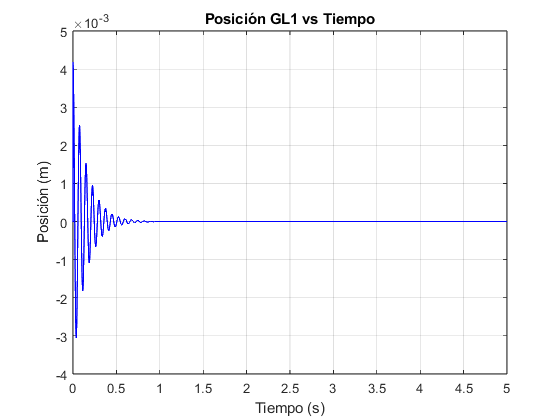


zitta = [zittam1;zittam2;zittam3];

wd = zeros(length(w),1);

for i = 1:length(w)
    wd(i) = w(i)*sqrt(1-zitta(i)^2);
end

q1 = [exp(-zitta(1)*w(1)*t) .* y0(1) .* cos(wd(1)*t);
      exp(-zitta(2)*w(2)*t) .* y0(2) .* cos(wd(2)*t);
      exp(-zitta(3)*w(3)*t) .* y0(3) .* cos(wd(3)*t)];

q2 = [exp(-zitta(1)*w(1)*t) .* zitta(1)/(sqrt(1-zitta(1)^2)) .* sin(wd(1)*t) .* y0(1);
      exp(-zitta(2)*w(2)*t) .* zitta(2)/(sqrt(1-zitta(2)^2)) .* sin(wd(2)*t) .* y0(2);
      exp(-zitta(3)*w(3)*t) .* zitta(3)/(sqrt(1-zitta(3)^2)) .* sin(wd(3)*t) .* y0(3)];

q3 = [y00(1)/wd(1) .* sin(wd(1)*t) .* exp(-zitta(1)*w(1)*t);
      y00(2)/wd(2) .* sin(wd(2)*t) .* exp(-zitta(2)*w(2)*t);
      y00(3)/wd(3) .* sin(wd(3)*t) .* exp(-zitta(3)*w(3)*t)];




q=q1+q2+q3;

X=autovec*q;

          
C = alpha * M + beta * K;


figure(1);
plot(t, X(1,:), 'b', 'LineWidth', 1);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Posición GL1 vs Tiempo');
grid on

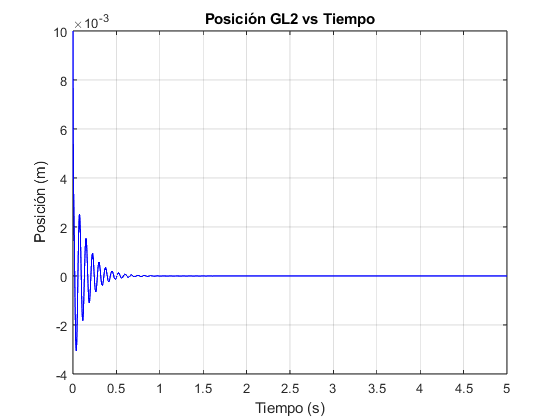


figure(2);
plot(t, X(2,:), 'b', 'LineWidth', 1);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Posición GL2 vs Tiempo');
grid on

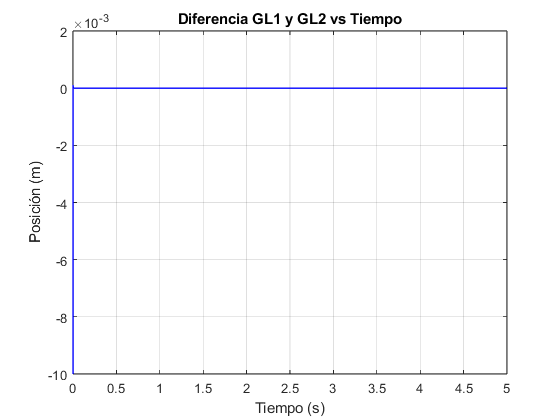

figure(3);
plot(t, X(1,:)-X(2,:), 'b', 'LineWidth', 1);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Diferencia GL1 y GL2 vs Tiempo');
grid on

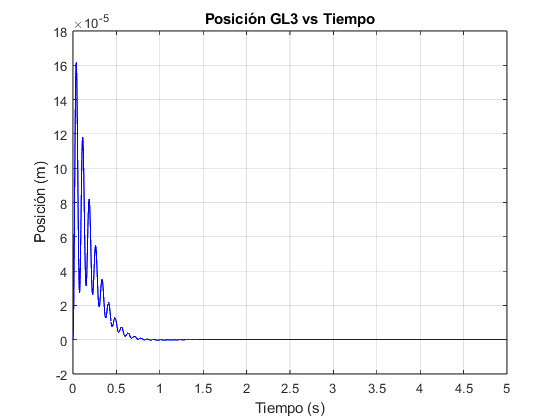


figure(4);
plot(t, X(3,:), 'b', 'LineWidth', 1);
xlabel('Tiempo (s)');
ylabel('Posición (m)');
title('Posición GL3 vs Tiempo');
grid on

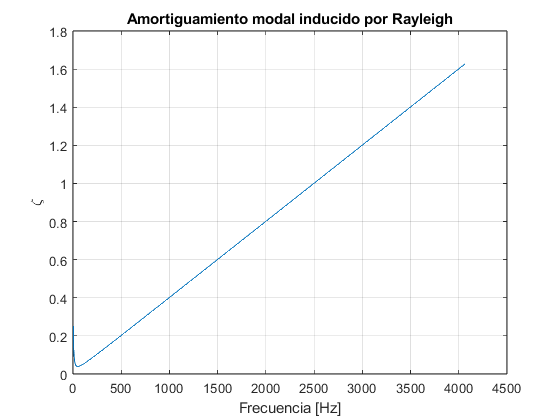

omega_range = linspace(0, 2*w(3), 1000);
zeta_all = 0.5 * (alpha ./ omega_range + beta * omega_range);
plot(omega_range/(2*pi), zeta_all);
xlabel('Frecuencia [Hz]');
ylabel('\zeta');
title('Amortiguamiento modal inducido por Rayleigh');
grid on;

El vector de estados por ahora es


$$\[
\mathbf{x} = \left[
\begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
\dot{x}_1 \\
\dot{x}_2 \\
\dot{x}_3
\end{array}
\right]
\]
$$


y el vector de salidas


$$\[
\mathbf{y} = \left[
\begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
\dot{x}_1 \\
\dot{x}_2 \\
\dot{x}_3 \\
\ddot{x}_1 \\
\ddot{x}_2 \\
\ddot{x}_3
\end{array}
\right]
\]
$$


n = size(M,1);
x0=[0;0;0];
v0=zeros(n,1);
A = [zeros(n), eye(n);
     -M\K, -M\C];
Bu = [zeros(n,1); M\eye(n)*[0; 1; -1]]; % por ejemplo, fuerza en masa 2
Bd = [zeros(n,1); M\eye(n)*[0; -1; 0]]; % por ejemplo, fuerza perturbadora en masa 2

B =[Bu,Bd];

% Armamos la nueva fila del C_out para aceleración
C_acc = -inv(M)*[K,C]  % [x, x_dot]

C_acc = 	1.0e+07 *

   -6.7521    6.7521         0   -0.0009    0.0009         0
    9.5535   -9.5551    0.0017    0.0012   -0.0012    0.0000
         0    0.0000   -0.0000         0    0.0000   -0.0000



% Nueva matriz C de salida
Cc = [eye(6); 
         C_acc];

% D de salida (sin entrada directa)
Du = [zeros(7,1);1/M(2,2);-1/M(3,3)];
Dd = [zeros(7,1);-1/M(2,2);0];
D = [Du,Dd];
sys = ss(A, [Bu,Bd], Cc, D);
f_transf = tf(sys)

f_transf =
 
  From input 1 to output...
                           9150 s^3 + 7.195e07 s^2 + 9.044e08 s + 3.592e09
   1:  ---------------------------------------------------------------------------------------
       s^6 + 2.081e04 s^5 + 1.636e08 s^4 + 4.403e09 s^3 + 1.196e12 s^2 + 1.469e13 s + 5.661e13
 
                     1.064 s^4 + 9176 s^3 + 7.195e07 s^2 + 9.044e08 s + 3.592e09
   2:  ---------------------------------------------------------------------------------------
       s^6 + 2.081e04 s^5 + 1.636e08 s^4 + 4.403e09 s^3 + 1.196e12 s^2 + 1.469e13 s + 5.661e13
 
                      -0.01 s^4 - 208 s^3 - 1.633e06 s^2 - 2.051e07 s - 0.02395
   3:  ---------------------------------------------------------------------------------------
       s^6 + 2.081e04 s^5 + 1.636e08 s^4 + 4.403e09 s^3 + 1.196e12 s^2 + 1.469e13 s + 5.661e13
 
                         9150 s^4 + 7.195e07 s^3 + 9.044e08 s^2 + 3.592e09 s
   4:  ---------------------------------------------------------------


% for i = 1:9
%     figure;
%     bode(sys(i,1));  % i-ésima salida respecto a la entrada
%     title(['Bode - Salida ', num2str(i)]);
%     grid on;
% end
% step(sys(7:9))

Agregado de subsistema electrico

A_aument = [A,[0;0;0;0;K_motor/m_movil;-K_motor/m_shaker];0 0 0 0 -K_motor/L K_motor/L -R/L]

A_aument = 	1.0e+07 *

         0         0         0    0.0000         0         0         0
         0         0         0         0    0.0000         0         0
         0         0         0         0         0    0.0000         0
   -6.7521    6.7521         0   -0.0009    0.0009         0         0
    9.5535   -9.5551    0.0017    0.0012   -0.0012    0.0000    0.0000
         0    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000
         0         0         0         0   -0.0027    0.0027   -0.0002


Bu_nueva = [0 0 0 0 0 0 1/L]';
Bd_nueva = [Bd;0];
B_nueva = [Bu_nueva Bd_nueva];

col_corr = [zeros(7,1); K_motor/m_movil;-K_motor/m_shaker]

col_corr =          0
         0
         0
         0
         0
         0
         0
   54.8936
   -0.5160


C_aument = [Cc col_corr; 0 0 0 0 0 0 1]

C_aument = 	1.0e+07 *

    0.0000         0         0         0         0         0         0
         0    0.0000         0         0         0         0         0
         0         0    0.0000         0         0         0         0
         0         0         0    0.0000         0         0         0
         0         0         0         0    0.0000         0         0
         0         0         0         0         0    0.0000         0
   -6.7521    6.7521         0   -0.0009    0.0009         0         0
    9.5535   -9.5551    0.0017    0.0012   -0.0012    0.0000    0.0000
         0    0.0000   -0.0000         0    0.0000   -0.0000   -0.0000
         0         0         0         0         0         0    0.0000


D_aument = [D;[0 0]]

D_aument =          0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
    1.0638   -1.0638
   -0.0100         0
         0         0


sys2 = ss(A_aument,B_nueva,C_aument,D_aument);
f_transf2 = tf(sys2)

f_transf2 =
 
  From input 1 to output...
                                2.485e08 s^3 + 1.954e12 s^2 + 2.456e13 s + 9.754e13
   1:  -----------------------------------------------------------------------------------------------------
       s^7 + 2.239e04 s^6 + 1.98e08 s^5 + 2.759e11 s^4 + 1.113e14 s^3 + 3.199e15 s^2 + 2.828e16 s + 8.938e16
 
                        2.889e04 s^4 + 2.492e08 s^3 + 1.954e12 s^2 + 2.456e13 s + 9.754e13
   2:  -----------------------------------------------------------------------------------------------------
       s^7 + 2.239e04 s^6 + 1.98e08 s^5 + 2.759e11 s^4 + 1.113e14 s^3 + 3.199e15 s^2 + 2.828e16 s + 8.938e16
 
                           -271.6 s^4 - 5.647e06 s^3 - 4.435e10 s^2 - 5.57e11 s + 87.51
   3:  -----------------------------------------------------------------------------------------------------
       s^7 + 2.239e04 s^6 + 1.98e08 s^5 + 2.759e11 s^4 + 1.113e14 s^3 + 3.199e15 s^2 + 2.828e16 s + 8.938e16
 
                              2.485

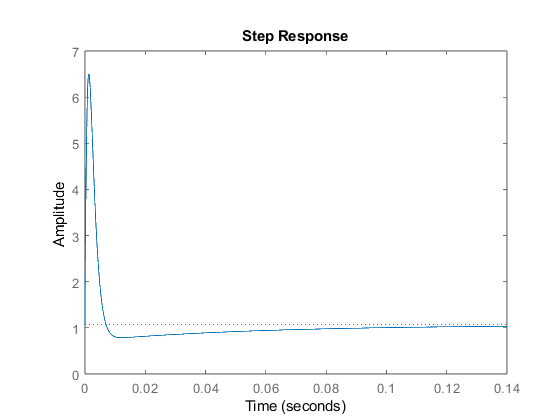

step(sys2(8,1))

co = ctrb(A_aument, Bu_nueva)  % matriz de controlabilidad

co = 	1.0e+24 *

         0         0         0    0.0000   -0.0000    0.0000   -0.0001
         0         0    0.0000   -0.0000    0.0000   -0.0000    0.0001
         0         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000
         0         0    0.0000   -0.0000    0.0000   -0.0001   -3.8998
         0    0.0000   -0.0000    0.0000   -0.0000    0.0001    5.5978
         0   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0008
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0014   -4.4457


rank_co = rank(co)

rank_co = 3

Esto significa que solo puedo controlar el la posición y velocidad del grado de libertad 2 pues es donde se aplica la fuerza de control, ademas de la corriente.

ob = obsv(A_aument, C_aument(8,:)) % Por que usar C_aument(8,:), que es la fila de la aceleracion que mido, hace que dé rango 2?

ob = 	1.0e+32 *

    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.0003   -0.0003    0.0000    0.0000   -0.0000    0.0000    0.0000
   -6.8054    6.8061   -0.0007   -0.0005    0.0005    0.0000   -0.0000


rank_ob = rank(ob);

if rank_ob == size(A_aument,1)
    disp('El sistema es observable.');
else
    disp(['NO es observable. Rank = ', num2str(rank_ob)]);
end

NO es observable. Rank = 2


ob_reducida = rref(ob)

ob_reducida =     1.0000         0   -1.0070 -107.3230  108.5326   -1.2096    0.0663
         0    1.0000   -1.0070 -107.3120  108.5215   -1.2095    0.0663
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0


Controlador P de corriente

K_motor_virtual = K_motor;

wc_corr = 5000; %Frecuencia de corte
R_control = wc_corr * L;

Amp = 2.5*g; %[m/s^2]
f = 50; %[Hz]
Ventana = 100;

PID en cascada. Controlador diseñado para Kmotor = 51.6 N/A= cte. Planta lineal

zita = 0.7;
wp = wpfreq(f)

wp = 25

ba = m_movil*(2*zita+1)*wp

ba = 56.4000

ksi = m_movil*(2*zita+1)*wp^2*10

ksi = 1.4100e+04

ksia = m_movil*wp^3

ksia = 1.4688e+04

function wp = wpfreq(f)
    % Tabla de frecuencia (Hz) y valores correspondientes de wp
    freq_table = [ ...
          5,  10,  20,  25,  30,  40,  50,  60,  70,  80, ...
         90, 100, 200, 300, 400, 500, 1000, 1500, 2000];

    wp_table = [ ...
         20,  15,  18,  20,  22,  25,  25,  25,  30,  30, ...
         40,  40,  50,  50,  70, 100,  200,  200,  200];

    % Interpolación lineal
    wp = interp1(freq_table, wp_table, f, 'linear', 'extrap');
end

